# Dekodowanie DTMF

[s, fs] = audioread('lab06/s1.wav');


Recznie:

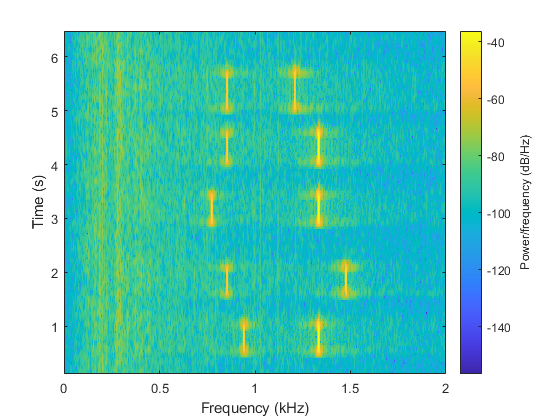

figure
spectrogram(s, 4096, 4096-512, [0:5:2000], fs);

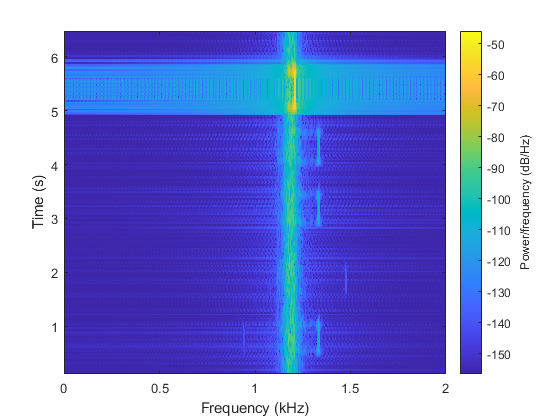

importbutter()

f       = 0:fs-1;
omega   = f*2*pi;

[b,a] = zp2tf(z,p,k); % z pierwiastkow na wielomian
[ha,wa]= freqs(b,a,omega);
% fvtool(b,a)

[bx,ax] = bilinear(b,a,fs);

Ya = filter(bx,ax,s);

figure
spectrogram(Ya, 4096, 4096-512, [0:5:2000], fs);